# Exploring x/y continuous data with gramm

In this example file, we will go further in exploring gramm's capabilities for data where some independent variables are continuous data.

We will load a partial dataset from a human movement science experiment

load example_movement.mat
T

T = 3170×15 table
    subject    session    trial_index    reference_direction    hit    m_movement_duration    m_dist    m_reaction_time                 target_pos                  valid_perc    valid_perc_session                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

In this dataset, we have four different subjects (`subject`), each coming for two sessions (`session`) on consecutive days at the lab. During each of these sessions they learn to control the displacement of a cursor on a screen, and their task is to reach targets with the cursor. The targets are arranged at discrete angles (`reference direction`) in a circle around a starting point. The cursor is difficult to control, and as a marker for progress, we record whether they reach the target in time (`hit`), how long was their reaction time (`m_reaction_time`), their movement (`m_movement_duration`), and what was the distance covered by the cursor (`m_dist`). Each line corresponds to a trial (`trial_index`), and we transformed the index in percentage of time elapsed within session (`valid_perc`) or across sessions (`valid_perc_session`).

Here we will represent the evolution of the reaction time across trials for each subject (using `facet_grid()`). To treat sessions independently we will map them to color. 

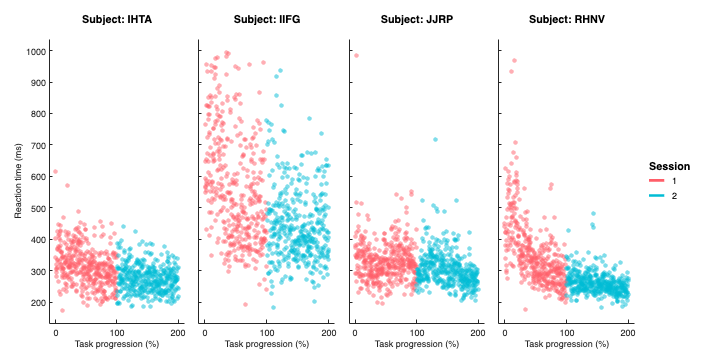

figure('Position',[100 100 800 400])

g=gramm('x',T.valid_perc_session,'y',T.m_reaction_time,'color',T.session);
g.facet_grid([],T.subject);
g.geom_point('alpha',0.5);
g.set_names('x','Task progression (%)','y','Reaction time (ms)','color','Session','column','Subject');
g.draw();

The points indicate a tendency for a decrease of the reaction time in all subjects, that tends to taper off in the second session. How can we add statistical layers that will help us visualize this ?

## Statistical layers for x/y data

There are several stat_ layers that allow this, they can be selected with the first drop-down menu.

#### stat_summary()

The most basic approach would simply be to bin data across the x-axis and represent descriptive statistics like the mean reaction time and its confidence interval in each bin. This can be done with `stat_summary()` using the `'bin_in' `argument which value sets the total number of bins across the x axis.

#### stat_smooth()

This uses a smoothing approach, either with a built-in fast smoothing or using underlying matlab tools from the curve fitting toolbox (splines, moving averages, loess, etc.). The `'lambda' `parameter sets the smoothing intensity. The confidence interval is computed by bootstrap

#### stat_glm()

This uses a generalized linear model (fitglm() from the statistics toolbox), which by default is configured as a classical linear regression. 

- The `'distribution' `parameter allows to pick the distribution of the response variable and corresponding link function. 

- When `'disp_fit'` is set to true, the model equation is displayed in the figure as well as significance stars for each term

- `'fullrange'` determines wheter the fit is displayed across the complete range of the x axis or only the data range.

#### stat_fit()

This uses an anonymous function to fit any non-linear model. Here we use an exponential function provided with the `'fun'` argument.  This function requires starting values for the fit parameters with `'StartPoint'`.

- `'intopt'` sets whether the shaded area represents the uncertainty of data or of the fitted function.

- When `'disp_fit'` is set to true, the model equation is displayed in the figure

 By default this method uses `fit()` from the curve fitting toolbox but can be configured to use `fitnlm()` from the statistics toolbox. 

**Pick the stat_ layer :**

vis = "stat_summary";

All these layers use a common 'geom' argument to specify how the results are displayed. Select one with this drop-down menu:

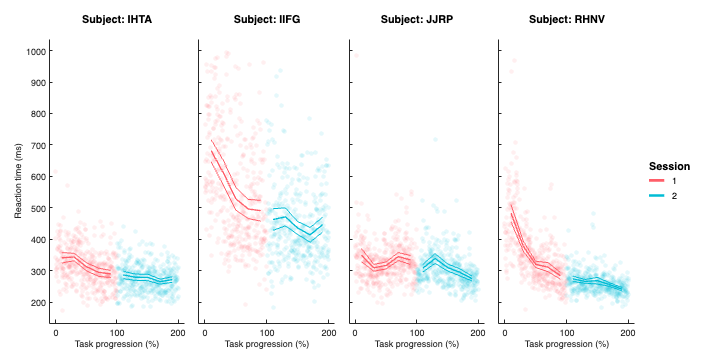

geom = 'lines';

figure('Position',[100 100 800 400])
g=gramm('x',T.valid_perc_session,'y',T.m_reaction_time,'color',T.session);
g.facet_grid([],T.subject);
g.geom_point('alpha',0.1);

switch vis                      %Call the correct gramm method depending on the chosen visualization
    case "stat_summary"
        g.stat_summary('geom',geom,'bin_in',10);
    case "stat_smooth"
        g.stat_smooth('geom',geom,'lambda',1e5);
    case "stat_glm"
        g.stat_glm('geom',geom,'distribution','inverse gaussian','disp_fit',false,'fullrange',false);
    case "stat_fit"
        g.stat_fit('geom',geom,'fun',@(a,b,c,x)a.*exp(x.*b)+c,'StartPoint',[1000 -0.01 150],'intopt','functional','disp_fit',false);
end

g.set_names('x','Task progression (%)','y','Reaction time (ms)','color','Session','column','Subject');
g.draw();